Sine Wave

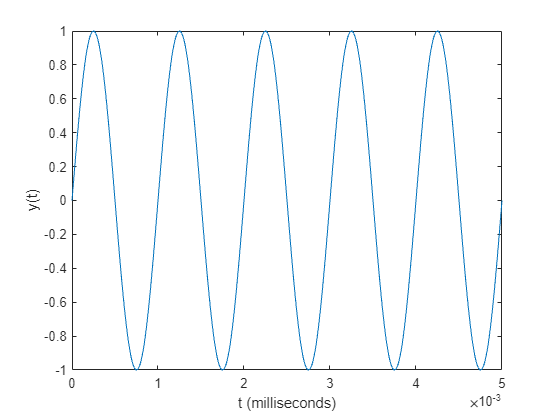

% define pass-band frequency
f1 = 1000; % [Hz]
% define sampling period
Ts = 5.e-6; % [s]
% define time interval
t = 0.:Ts:5e-3; % [s]
L = length(t);
% create signal
y = sin(2*pi*f1*t);
% plot signal
figure(1)
plot(t,y)
xlabel("t (milliseconds)")
ylabel("y(t)")

Sine FFT

% calculate FFT of the signal
Y = fft(y);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

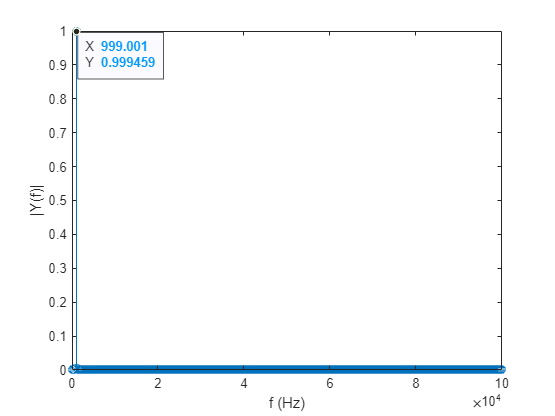

P1(2:end-1) = 2*P1(2:end-1);
% sampling frequency
Fs = 1/Ts;
f = Fs*(0:(L/2))/L;
figure(2)
stem(f,P1)
xlabel("f (Hz)")
ylabel("|Y(f)|")

Square Wave

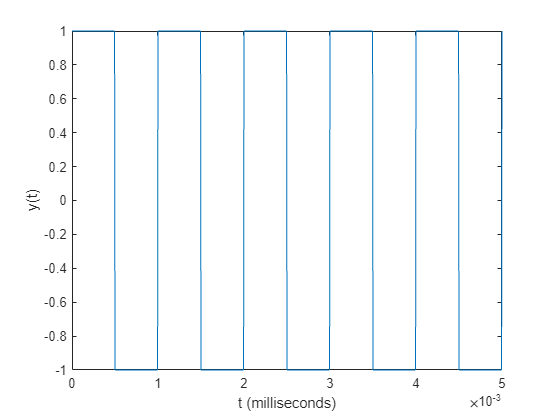

% define pass-band frequency
f1 = 1000; % [Hz]
% define sampling period
Ts = 5.e-6; % [s]
% define time interval
t = 0.:Ts:5e-3; % [s]
L = length(t);
% create signal
y = square(2*pi*f1*t);
% plot signal
figure(1)
plot(t,y)
xlabel("t (milliseconds)")
ylabel("y(t)")

Square Wave FFT

% calculate FFT of the signal
Y = fft(y);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

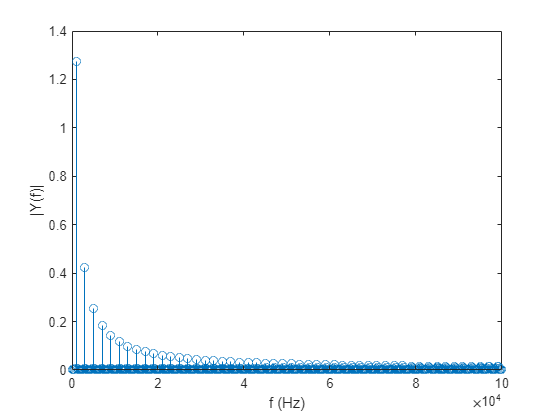

P1(2:end-1) = 2*P1(2:end-1);
% sampling frequency
Fs = 1/Ts;
f = Fs*(0:(L/2))/L;
figure(2)
stem(f,P1)
xlabel("f (Hz)")
ylabel("|Y(f)|")

Triangle Wave

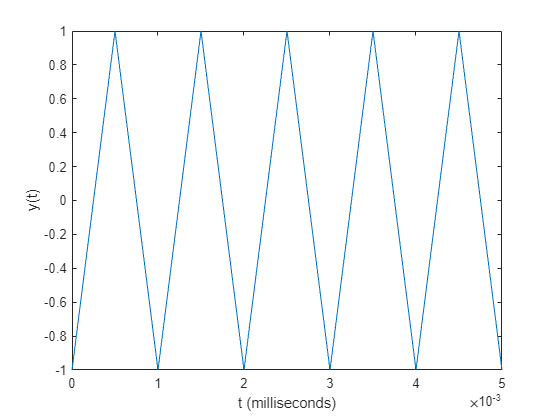

% define pass-band frequency
f1 = 1000; % [Hz]
% define sampling period
Ts = 5.e-6; % [s]
% define time interval
t = 0.:Ts:5e-3; % [s]
L = length(t);
% create signal
y = sawtooth(2*pi*f1*t,0.5);
% plot signal
figure(1)
plot(t,y)
xlabel("t (milliseconds)")
ylabel("y(t)")

Triangle Wave FFT

% calculate FFT of the signal
Y = fft(y);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

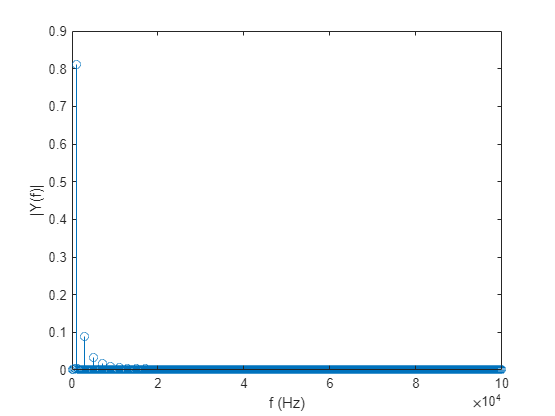

P1(2:end-1) = 2*P1(2:end-1);
% sampling frequency
Fs = 1/Ts;
f = Fs*(0:(L/2))/L;
figure(2)
stem(f,P1)
xlabel("f (Hz)")
ylabel("|Y(f)|")